clear
clc
close all

Parámetros

m_movil = 0.94; % [kg] Masa plato + bobina
m_cubesat = 1.33; %[kg] Masa Cubesat
m_total = m_movil + m_cubesat;
bm = 1000; % [Ns/m] coeficiente de fricción viscosa (a confirmar)
k_resorte = 15761; % [N/m]
K_motor = 51.6; %[N/A] [Vs/m] constante de back EMF y de fuerza (valen lo mismo)
g = 9.81; %[m/s^2] Aceleración de la gravedad

R = 3; %[Ohm] Resistencia del bobinado
L = 1.9e-3; %[H] Inductancia del bobinado (medida a 1000Hz)

Pot_max = 75 ; %[W] Potencia máxima
I_max = sqrt(Pot_max/R); % [A]
V_max = sqrt(Pot_max*R); % [V]

K_motor_virtual = K_motor;
bm_virtual = bm;
m_total_virtual = m_total;

Espacio de Estados

%[x
% x' 
% i]

A = [0 1 0;
   -k_resorte/m_total -bm/m_total K_motor/m_total;
    0 -K_motor/L -R/L];
Bu = [0 ; 0 ; 1/L];
Bd = [0; -1/m_total ; 0];
C_acc = [-k_resorte/m_total -bm/m_total K_motor/m_total];
C_pos = [1 0 0];
Du = [0];
Dd = [-1/m_total];


Realimentación completa de estados

Aaug = [A [0;0;0]; C_pos 0]

Aaug = 	1.0e+04 *

         0    0.0001         0         0
         0   -0.0441    0.0023         0
         0   -2.7158   -0.1579         0
    0.0001         0         0         0


Baug = [Bu;0]

Baug =          0
         0
  526.3158
         0


wn = 600;
z = 1/sqrt(2);
p1 = [1 2*z*wn wn^2];
p2 = [0 1 3*z*wn];
p3 = [0 1 6*z*wn];
p = conv(p1,p2)

p = 	1.0e+08 *

         0    0.0000    0.0000    0.0144    4.5821


p = conv(p,p3)

p = 	1.0e+12 *

         0         0    0.0000    0.0000    0.0000    0.0041    1.1664


polos = roots(p)

polos = 	1.0e+03 *

  -2.5456 + 0.0000i
  -1.2728 + 0.0000i
  -0.4243 + 0.4243i
  -0.4243 - 0.4243i


Kaug = acker(Aaug,Baug,polos)

Kaug = 	1.0e+07 *

    0.0345    0.0000    0.0000    9.7494


K = Kaug(1, 1:3)

K = 	1.0e+05 *

    3.4469    0.0036    0.0001


Ki = Kaug(4)

Ki = 9.7494e+07

M = A - Bu*K;
X = C_pos * (M \ Bu)  

X = -2.9011e-06

kr = -1 / X 

kr = 3.4469e+05

Br = [0 0 0 -1]'

Br =      0
     0
     0
    -1


sys = ss(Aaug - Baug*Kaug, Baug*kr+Br, [C_pos 0], 0);
Hc = tf(sys)

Hc =
 
                 4.124e09 s + 1.166e12
  ----------------------------------------------------
  s^4 + 4667 s^3 + 6.84e06 s^2 + 4.124e09 s + 1.166e12
 
Continuous-time transfer function.



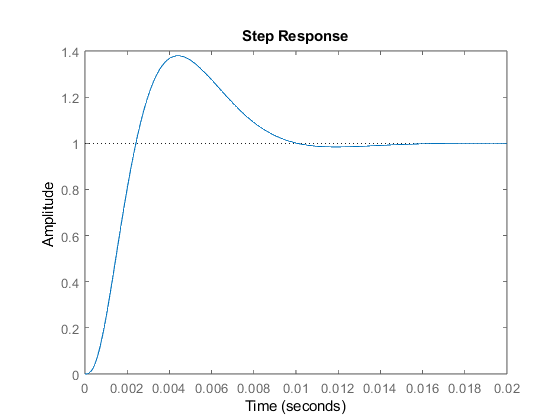

step(Hc)

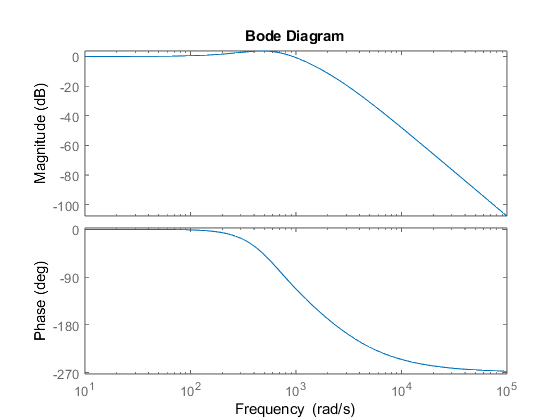

bode(sys)